# Homework 1

## Question 1

Different arguments for "shape":

- full: the convolution begins with the bottom right cell of the kernel overlapping with the top left cell of the image, and the rest of the kernel is multiplied by 0, resulting in the black corners at the edges. The size of the convoluted image is larger than the size of the original image

- same: the convolution begins with the center of the kernel overlapping with the top left cell of the image, and zero padding is used as necessary to account for the portions of the kernel that are not overlapping the image. The size of the resulting image is the same as the size of the original image.

- valid: the convolution begins with the top left cells of the kernel and the image aligned, so that no part of the kernel is outside the image. This means that no zero-padding is necessary, resulting in no dark edges in the resulting image. However, the convoluted image is smaller than the original image.

flat_test1 = ones(20)*100; % creating flat test image
constant_kernel1 = ones(5).*3; % creating kernel
size(flat_test1)

ans =     20    20


full_shape1 = conv2(flat_test1, constant_kernel1, "full"); % creating convoluted image with 'full' shape
size(full_shape1) % size of matrix

ans =     24    24


same_shape1 = conv2(flat_test1, constant_kernel1, "same"); % creating convoluted image with 'same' shape
size(same_shape1) % size of matrix

ans =     20    20


valid_shape1 = conv2(flat_test1, constant_kernel1, "valid"); % creating convoluted image with 'valid' shape
size(valid_shape1) % size of matrix

ans =     16    16


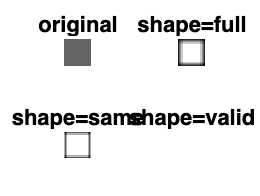


% plotting images
figure
subplot(2,2,1)
imshow(flat_test1, [0,255])
title("original")
subplot(2,2,2)
imshow(full_shape1, [])
title("shape=full")
subplot(2,2,3)
imshow(same_shape1, [])
title("shape=same")
subplot(2,2,4)
imshow(valid_shape1, [])
title("shape=valid")

## Question 2

In order to enhance the edges of the image, I did unsharp mask processing. To do this, I first filtered the image using a Gaussian filter. Then, I subtracted the filtered image from the original to get the edges of the images. Finally, I added the edges to the blurred image to create a new, sharpened image. In this process, I manipulated the Gaussian kernel to get different results. The parameters to manipulate were hsize, which is the size of the kernel, and sigma, which is the standard deviation of the kernel. I started with a 5x5 kernel with a standard deviation of 0.5, but I found that using an hsize of 13 and a sigma of 7 yielded the best results.

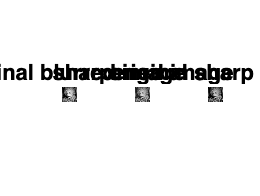

% unsharp mask processing
einstein_blur = im2double(imread("EINSTEIN_8bit-blur.tif"));
einstein_img = im2double(imread("EINSTEIN_8bit.tif"));
gauss_filter = fspecial('gaussian', 13, 7); % creating kernel
einstein_gauss_blur = conv2(einstein_blur, gauss_filter, "same"); % convoluting
einstein_edges = einstein_blur - einstein_gauss_blur; % creating edges
sharpened_einstein = einstein_blur + einstein_edges; % addiing edges
%{
parameters: hsize, sigma
%}

% plotting images
figure
subplot(1,3,1)
imshow(einstein_blur, [])
title("original blurred image")
subplot(1,3,2)
imshow(sharpened_einstein, [])
title("sharpened image")
subplot(1,3,3)
imshow(einstein_img, [])
title("original sharp image")


% figure
% for i=2:17
%     subplot(4,4,i-1)
%     filter_test = fspecial('gaussian', 13, i); % creating kernel
%     img_blurred = conv2(einstein_blur, filter_test, "same"); % convoluting
%     img_edges = einstein_blur - img_blurred; % creating edges
%     img_sharp = einstein_blur + einstein_edges;
%     imshow(img_sharp)
% end

## Question 3

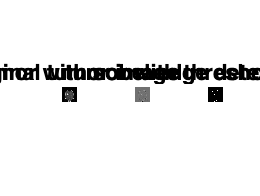

tumor_img = load("TUMOR.MAT").tumor; % loading tumor image
sobel_filter = fspecial("sobel"); % creating filter
tumor_sobel = imfilter(tumor_img, sobel_filter); % filtering image
tumor_sobel_img = uint8(255 * mat2gray(tumor_sobel)); % modifying image
tumor_threshold = im2bw(tumor_sobel_img,0.55); % thresholding filtered image
figure
subplot(1,3,1)
imshow(tumor_img, [])
title("original tumor image")
subplot(1,3,2)
imshow(tumor_sobel_img)
title("tumor with sobel edge detection")
subplot(1,3,3)
imshow(tumor_threshold)
title("tumor with threshold applied")

## Question 4

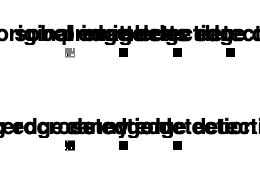

% creating filtered images
edges_img = load("edges.MAT").edges;
sobel_edges = edge(edges_img,"sobel");
prewitt_edges = edge(edges_img, "prewitt");
roberts_edges = edge(edges_img, "roberts");
log_edges = edge(edges_img, "log");
zc_edges = edge(edges_img,"zerocross");
canny_edges = edge(edges_img, "canny");

% displaying filtered images
figure
subplot(2,4,1)
imshow(edges_img, [])
title("original image")
subplot(2,4,2)
imshow(sobel_edges, [])
title("sobel edge detection")
subplot(2,4,3)
imshow(prewitt_edges, [])
title("prewitt edge detection")
subplot(2,4,4)
imshow(roberts_edges, [])
title("roberts edge detection")
subplot(2,4,5)
imshow(log_edges, [])
title("log edge detection")
subplot(2,4,6)
imshow(zc_edges, [])
title("zerocross edge detection")
subplot(2,4,7)
imshow(canny_edges, [])
title("canny edge detection")

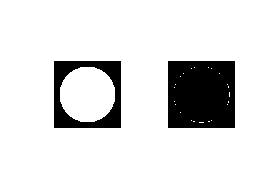


% 4b
disk = load("disk_img.mat").disk_img;
sobel_disk = edge(disk, "sobel");
figure
subplot(1,2,1)
imshow(disk, [])
subplot(1,2,2)
imshow(sobel_disk, [])

- biphasic: log, zerocross. The resulting b&w image seems to show two "edges": one for the black border, and one for the white border.

- The sobel filter is rotationally invariant, as shown in the filtered disk image, in which sobel is able to detect edges 360 degrees around.

- I think Canny is the best filter for this application because of its ability to consistently identify weak edges. Sobel, Prewitt, and Roberts do not detect weak edges at all. LOG and zerocross were able to detect the weak edges in the top left figure, but not the ones in the top right. Canny was able to detect all the edges that the other filters could as well as the weak edges in the figure in the top right.

## Question 5

    In order to do Canny Edge detection, the image must first undergo noise reduction. This is done by applying a Gaussian blur filter on the image. Then, a gradient is calculated using an edge detection filter, such as a Sobel filter. The edges are made more thin using a process called non-maximum suppression. The image is double thresholded; a high threshold is used to identify strong edges, and a low threshold is used to identify pixels that are not relevant. Pixel values that fall in between the high and low threshold undergo hysteresis thresholding. In this method, a pixel is considered relevant if it is between the two thresholds and is connected to a known edge (or a known relevant pixel).